### Problem：${y^{\prime } }^{\prime } +y=x^2 \left(x\in \left\lbrack 0,1\right\rbrack \right)$，$y\left(0\right)=0，y^{\prime } \left(0\right)=1$

1.$Ritzmethod$ **(approximate solution using 1 to 4 terms)**

clc;clear
syms C1 C2 C3 C4 y(x)
C=[C1,C2,C3,C4];
C0=zeros(4,4);
eq=zeros(4,1);
X=[x;x^2;x^3;x^4];
y(x)=0;
for i=1:4
    y(x)=y(x)+C(i)*x^i;
    f=simplify(0.5*diff(y,x)^2-0.5*y^2+x^2*y);
    F=int(f,[0,1])-y(1);
    eq=[diff(F,C1);diff(F,C2);diff(F,C3);diff(F,C4)]==0;
    c=solve(eq,[C1,C2,C3,C4]);
    C0(i,:)=[c.C1,c.C2,c.C3,c.C4];
end
disp('y'==C0*X);

$$\left(\begin{array}{c} y=\frac{9\,x}{8}\\ y=\frac{180\,x}{139}-\frac{21\,x^{2}}{139}\\ y=-\frac{175\,x^{3}}{7108}-\frac{203\,x^{2}}{1777}+\frac{2280\,x}{1777}\\ y=\frac{873896121833417\,x^{4}}{9007199254740992}-\frac{7878326174222841\,x^{3}}{36028797018963968}+\frac{2345545175619117\,x^{2}}{1152921504606846976}+\frac{1422951464801701\,x}{1125899906842624} \end{array}\right)$$

y0=(C0*X);
fplot(y0,[0,1])
hold on;
xlabel("x")
ylabel("y")
title("y-x")

legend("Position", [0.4130 0.1684 1.0006, 0.1753]);

2.$Exactsolution$

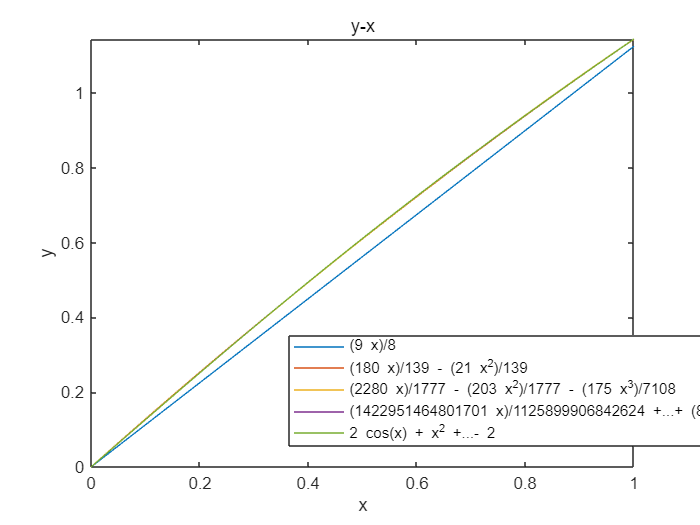

clc;clear
syms x y(x)
eq0=-diff(y,x,2)-y+x^2==0;
y=dsolve(eq0,y(0)==0,subs(diff(y,x,1),x,1)==1);
fplot(y,[0,1])

disp('y'==y)

$$y=2\,\cos\left(x\right)+x^{2}+\frac{\sin\left(x\right)\,\left(2\,\sin\left(1\right)-1\right)}{\cos\left(1\right)}-2$$